clear
load('ExampleData.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime)

positionTime =          0
   36.3390
   37.3520
   38.3510
   39.3510
   40.3510
   41.3370
   42.3280
   43.3120
   44.3130


accelTime=timeElapsed(accelDatetime)

accelTime =          0
    0.0190
    0.0380
    0.0570
    0.0760
    0.0950
    0.1140
    0.1330
    0.1520
    0.1710


earthCirc = 24901;
totaldis = 0;

for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1);   % The second longitude
    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;
    
    totaldis = totaldis + dis;
end

stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.4093 miles


disp(['You took ', num2str(steps) ' steps'])

You took 864.4514 steps


load ActivityLogs
head(sitAcceleration)

           Timestamp               X         Y         Z   
    ________________________    _______    ______    ______

    20-Jul-2023 13:34:44.644      2.138    3.1268    10.077
    20-Jul-2023 13:34:44.724     1.1684    2.8754    8.8657
    20-Jul-2023 13:34:44.804    0.93134     3.146     9.335
    20-Jul-2023 13:34:44.884    0.69192    3.2729     8.746
    20-Jul-2023 13:34:44.964     1.1851    3.3974    9.1722
    20-Jul-2023 13:34:45.044     1.1803    3.4093    9.1626
    20-Jul-2023 13:34:45.124     1.0654    3.3423    8.6335
    20-Jul-2023 13:34:45.204     1.5778    3.5147    9.7779



sitLabel = 'sitting';
sitLabel = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitAcceleration.Activity = sitLabel

sitAcceleration = 390×4 timetable
           Timestamp                X          Y         Z       Activity
    ________________________    _________    ______    ______    ________

    20-Jul-2023 13:34:44.644        2.138    3.1268    10.077    sitting 
    20-Jul-2023 13:34:44.724       1.1684    2.8754    8.8657    sitting 
    20-Jul-2023 13:34:44.804      0.93134     3.146     9.335    sitting 
    20-Jul-2023 13:34:44.884      0.69192    3.2729     8.746    sitting 
    20-Jul-2023 13:34:44.964       1.1851    3.3974    9.1722    sitting 
    20-Jul-2023 13:34:45.044       1.1803    3.4093    9.1626    sitting 
    20-Jul-2023 13:34:45.124       1.0654    3.3423    8.6335    sitting 
    

% Repeat for walking data
walkLabel = 'walking';
walkLabel = repmat(walkLabel, size(walkAcceleration, 1), 1);
walkAcceleration.Activity = walkLabel;

% Repeat for running data
runLabel = 'running';
runLabel = repmat(runLabel, size(runAcceleration, 1), 1);
runAcceleration.Activity = runLabel;
allAcceleration = [sitAcceleration; walkAcceleration; runAcceleration];
allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", false)

allAcceleration = 1121×4 table
        X          Y         Z       Activity
    _________    ______    ______    ________

        2.138    3.1268    10.077    sitting 
       1.1684    2.8754    8.8657    sitting 
      0.93134     3.146     9.335    sitting 
      0.69192    3.2729     8.746    sitting 
       1.1851    3.3974    9.1722    sitting 
       1.1803    3.4093    9.1626    sitting 
       1.0654    3.3423    8.6335    sitting 
       1.5778    3.5147    9.7779    sitting 
      0.76375    3.2801       8.6    sitting 
      0.98881    3.2537    9.2344    sitting 
       1.7238    4.1276    8.8992    sitting 
    -0.019154    2.9592     9.007    sitting 
      0.87149    2.6456     9.098    sitting 
       1.0343    3.0311    9.3781    sitting 
       1.1971    3.3686    9.2129    sitting 
      0.93134    3.4476     8.928    sitting 


classificationLearner

unknownAcceleration % preview data to ensure the correct format

unknownAcceleration = 2174×3 timetable
           Timestamp                X           Y           Z    
    ________________________    _________    _______    _________

    26-Jul-2023 13:27:54.764      -3.1795    -9.1123       1.1516
    26-Jul-2023 13:27:54.844      -3.0287    -9.2703       1.3144
    26-Jul-2023 13:27:54.924      -3.2178    -9.0285       1.2546
    26-Jul-2023 13:27:55.004      -3.1603    -9.1243       1.2761
    26-Jul-2023 13:27:55.084      -3.0574    -9.1051       1.1947
    26-Jul-2023 13:27:55.164      -2.9999    -8.8897       1.4581
    26-Jul-2023 13:27:55.244      -2.1596    -8.2696    -0.011971
    26-Jul-2023 13:27:55.324      -1.6496    -9.1842      -1.8483
    26-Jul-2023 13:2

justAcc = timetable2table(unknownAcceleration, "ConvertRowTimes", false);
yfit = trainedModel.predictFcn(justAcc)

yfit = 2174×7 char array
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'running'
    'walking'
    'running'
    'running'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walking'
    'walk

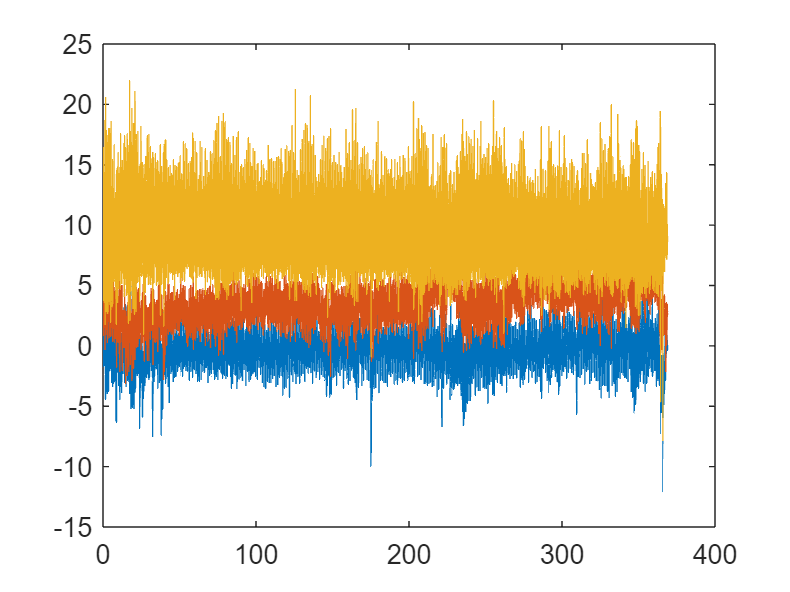

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
hold off

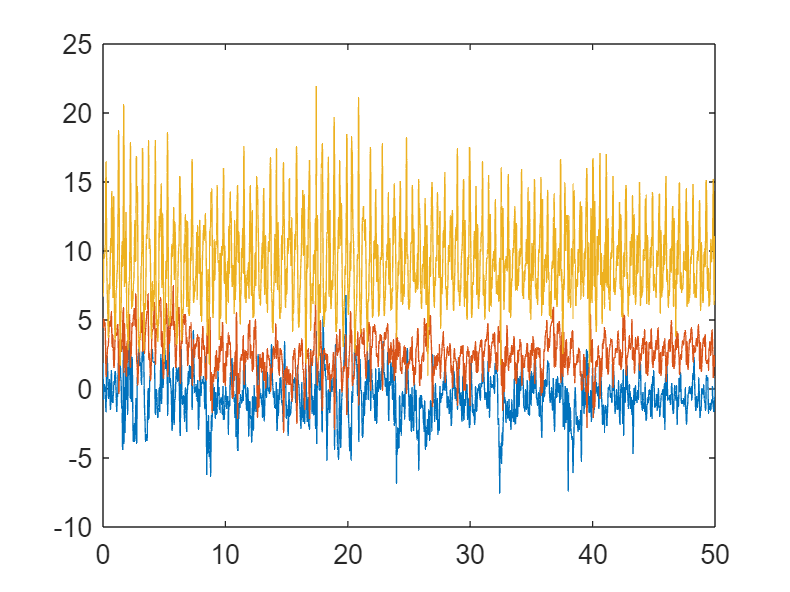

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
hold off

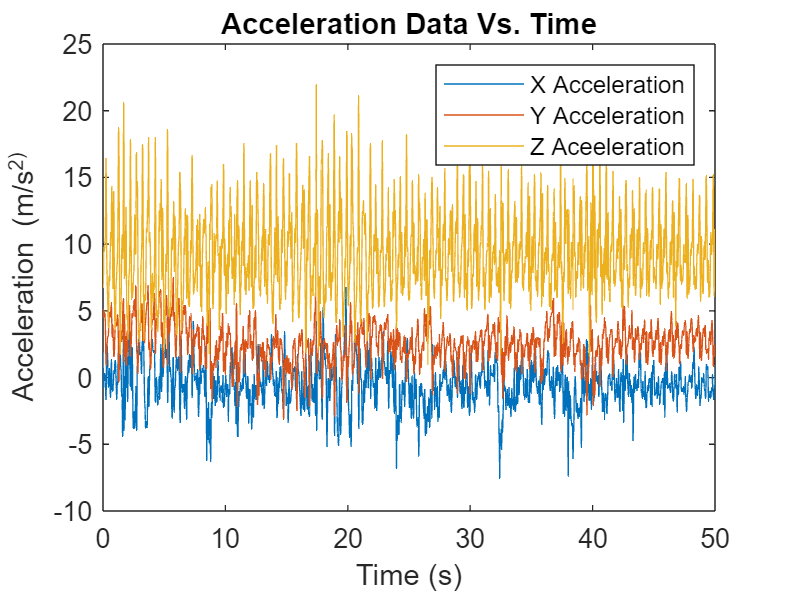

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])

legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

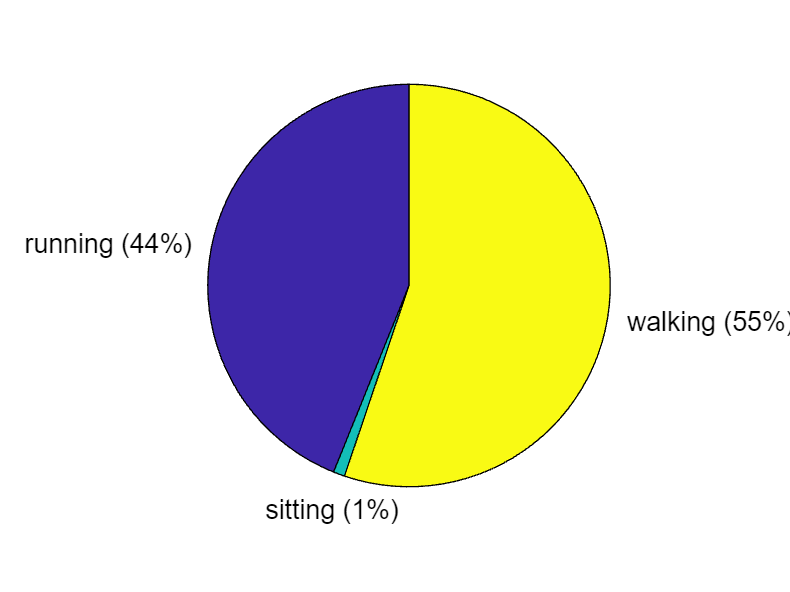


yfitcat = categorical(cellstr(yfit)); % convert to correct data type for histogram
pie(yfitcat)